# Discrete-Time Signals: Operations, Manipulation and Audio Applications

**Digital Signal Processing – lecture live script.** This script walks through (almost) everything you can do to a discrete-time signal $x[n]$: generate it, scale it, shift it, fold it, resample it, add and multiply it, convolve it, correlate it, filter it and transform it. It ends by using exactly the same operations on real music: turning the volume up and down, slow motion, fast forward, pitch shifting, echo, reverb and more.

**How to use.** Run the script one section at a time (**Run Section**, Ctrl+Enter) with the output shown inline (View tab → Output Inline). It needs base MATLAB R2019b or newer (for `tiledlayout`); no toolbox is required. Every helper function is a local function in the last section of the script.

**Audio.** Turn your speakers on. Section 12 reuses the variables created in 12.1, so run 12.1 first. Each clip is announced with a short label and plays to the end before the next one starts.

## 0. Setup

Clear the workspace and set some plot defaults that make every figure in the script easier to read.

clear; clc; close all
set(groot, 'defaultAxesFontSize', 11, ...
           'defaultAxesXGrid', 'on', 'defaultAxesYGrid', 'on', ...
           'defaultLineLineWidth', 1.4);

## 1. What is a discrete-time signal?

A discrete-time signal is a sequence of numbers $x[n]$ defined only for integer $n$. It usually comes from sampling a continuous-time signal every $T_s = 1/F_s$ seconds:


$$x[n] = x_a(nT_s), \qquad T_s = \frac{1}{F_s}$$


**MATLAB pitfall:** MATLAB arrays start at index 1, but a signal may start at $n=-5$ or $n=0$. Whenever the index matters, store the index vector `n` next to the value vector `x` and always plot with `stem(n, x)`.

n = -5:10;                    % index vector: any integers, may be negative
x = 0.8.^n .* (n >= 0);       % x[n] = 0.8^n u[n]

table(n.', x.', 'VariableNames', {'n', 'x_n'})     % (index, value) pairs

figure
stem(n, x, 'filled'); xlabel('n'); ylabel('x[n]'); title('x[n] = 0.8^n u[n]')

Sampling a continuous signal: a 2 Hz cosine sampled at $F_s = 20$ Hz.

Fs = 20;  Ts = 1/Fs;                 % 20 samples per second
t  = 0:1e-3:1;                       % (almost) continuous time axis
xa = cos(2*pi*2*t);                  % analog signal: 2 Hz cosine
n  = 0:Fs;                           % sample indices covering one second
xn = cos(2*pi*2*n*Ts);               % x[n] = xa(n*Ts)

figure
plot(t, xa, 'Color', [0.7 0.7 0.7]); hold on
stem(n*Ts, xn, 'filled'); hold off
xlabel('t (s)'); legend('x_a(t)', 'x[n] = x_a(nT_s)'); title('Sampling a 2 Hz cosine at F_s = 20 Hz')

## 2. Generating elementary signals

Almost every signal can be built from a few building blocks. The most important one is the **unit impulse** $\delta[n]$, because any sequence is a weighted sum of shifted impulses:


$$x[n] = \sum_{k=-\infty}^{\infty} x[k]\,\delta[n-k]$$


rng(1)
n = -10:20;
u      = double(n >= 0);                              % unit step u[n]
delta  = double(n == 0);                              % unit impulse
ramp   = n .* u;                                      % unit ramp
decay  = 0.85.^n .* u;                                % decaying real exponential
grow   = 1.15.^n .* u;                                % growing real exponential
cplx   = exp((-0.08 + 1j*pi/6) * n) .* u;             % damped complex exponential
sine   = sin(2*pi*n/12);                              % sinusoid, period 12 samples
sq     = sign(sin(2*pi*n/12));                        % square wave
saw    = 2*mod(n/12, 1) - 1;                          % sawtooth
tri    = 2*abs(2*mod(n/12, 1) - 1) - 1;               % triangle wave
rectp  = double(abs(n) <= 3);                         % rectangular pulse
sinc_n = sincf(n/4);                                  % sampled sinc
chirp_n = sin(2*pi*(0.02*n + 0.003*n.^2)) .* u;       % linear chirp (frequency rises)
wn     = randn(size(n));                              % Gaussian white noise
un     = rand(size(n));                               % uniform white noise

sigs  = {delta, u, ramp, decay, grow, real(cplx), imag(cplx), sine, ...
         sq, saw, tri, rectp, sinc_n, chirp_n, wn, un};
names = {'\delta[n]', 'u[n]', 'ramp n u[n]', '0.85^n u[n]', '1.15^n u[n]', ...
         'Re of complex exp.', 'Im of complex exp.', 'sinusoid', ...
         'square wave', 'sawtooth', 'triangle', 'rectangular pulse', ...
         'sinc(n/4)', 'chirp', 'Gaussian noise', 'uniform noise'};

figure('Position', [100 100 1000 700])
tiledlayout(4, 4, 'TileSpacing', 'compact', 'Padding', 'compact')
for k = 1:numel(sigs)
    nexttile; stemplot(n, sigs{k}, names{k});
end

## 3. Amplitude (point-wise) operations

These operations act on each sample independently: $y[n] = f(x[n])$. They change the *height* of the signal, never its time axis. Multiplying two signals sample by sample is also point-wise, and it is the basis of modulation and windowing.

rng(1)
n = 0:39;
x = sin(2*pi*n/20);                              % test signal, period 20

ops = { x,                       'x[n]  (original)'; ...
        2*x,                     'amplify: 2x[n]'; ...
        0.5*x,                   'attenuate: 0.5x[n]'; ...
        -x,                      'invert: -x[n]'; ...
        x + 1,                   'DC offset: x[n]+1'; ...
        abs(x),                  'full-wave rectify: |x[n]|'; ...
        max(x, 0),               'half-wave rectify'; ...
        x.^2,                    'square: x[n]^2'; ...
        max(min(1.5*x,1),-1),    'hard clip: 1.5x[n] limited to +-1'; ...
        x .* cos(2*pi*n/4),      'modulate: x[n]cos(2\pi n/4)'; ...
        x + 0.5*sin(2*pi*n/5),   'add a 2nd sinusoid'; ...
        x + 0.2*randn(size(n)),  'add noise' };

figure('Position', [100 100 1000 650])
tiledlayout(3, 4, 'TileSpacing', 'compact', 'Padding', 'compact')
for k = 1:size(ops, 1)
    nexttile; stemplot(n, ops{k,1}, ops{k,2});
end

## 4. Operations on the time index

### 4.1 Shift, fold and scale: one idea, y[n] = x[g(n)]

Every operation on the independent variable is the same recipe: to get $y[n]$, look up $x$ at the index $g(n)$.

- Delay by $k$: $y[n] = x[n-k]$ (the graph moves right).

- Advance by $k$: $y[n] = x[n+k]$ (the graph moves left).

- Folding (time reversal): $y[n] = x[-n]$.

- Scaling: $y[n] = x[2n]$ (down-sampling) or $y[n] = x[n/2]$ (up-sampling, zeros where $n/2$ is not an integer).

**Order matters.** Fold-then-delay gives $x[2-n]$ but delay-then-fold gives $x[-n-2]$. The helper `xat(x, nx, q)` returns $x$ at the indices `q`, and zero outside the stored range.

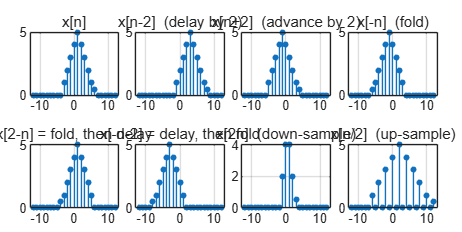

nx = -3:6;                                % indices of the stored samples
x  = [1 2 3 4 5 4 3 2 1 0.5];             % x[n] for n = -3..6
n  = -12:12;                              % common display axis

sigs = { xat(x,nx,n),      'x[n]'; ...
         xat(x,nx,n-2),    'x[n-2]  (delay by 2)'; ...
         xat(x,nx,n+2),    'x[n+2]  (advance by 2)'; ...
         xat(x,nx,-n),     'x[-n]  (fold)'; ...
         xat(x,nx,2-n),    'x[2-n] = fold, then delay'; ...
         xat(x,nx,-n-2),   'x[-n-2] = delay, then fold'; ...
         xat(x,nx,2*n),    'x[2n]  (down-sample)'; ...
         xat(x,nx,n/2),    'x[n/2]  (up-sample)' };

figure('Position', [100 100 1000 500])
tiledlayout(2, 4, 'TileSpacing', 'compact', 'Padding', 'compact')
for k = 1:size(sigs, 1)
    nexttile; stemplot(n, sigs{k,1}, sigs{k,2});
end

The same thing done by *index bookkeeping*: a delay only changes the labels of the samples, a fold reverses the samples and negates the labels. Both routes give identical results.

[xd, nd] = sigshift(x, nx, 2);            % same samples, index labels + 2
[xf, nf] = sigfold(x, nx);                % reversed samples, index labels negated

same_delay = isequal(xat(xd, nd, n), xat(x, nx, n-2))

same_delay = logical
   1


same_fold  = isequal(xat(xf, nf, n), xat(x, nx, -n))

same_fold = logical
   1


### 4.2 Adding and multiplying signals with different supports

Two sequences can only be added when they are aligned on a common index axis. Zero-padding both to the union of their supports does that.

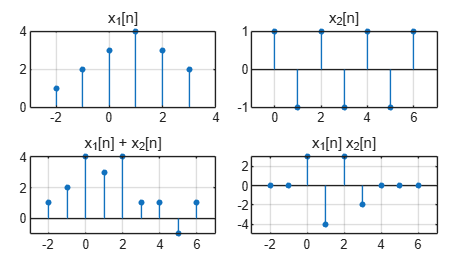

n1 = -2:3;   x1 = [1 2 3 4 3 2];
n2 =  0:6;   x2 = [1 -1 1 -1 1 -1 1];

[ys, ns] = sigadd(x1, n1, x2, n2);        % x1[n] + x2[n]
[yp, np] = sigmult(x1, n1, x2, n2);       % x1[n] * x2[n]

figure('Position', [100 100 900 500])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n1, x1, 'x_1[n]')
nexttile; stemplot(n2, x2, 'x_2[n]')
nexttile; stemplot(ns, ys, 'x_1[n] + x_2[n]')
nexttile; stemplot(np, yp, 'x_1[n] x_2[n]')

### 4.3 Down-sampling, up-sampling and interpolation

**Down-sampling** by $M$ keeps every $M$-th sample: $y[n] = x[Mn]$. **Up-sampling** by $L$ inserts $L-1$ zeros between samples. The zero-stuffed signal is then low-pass filtered (an *interpolation filter*) to fill in the gaps. Here the filter is a triangle, which gives linear interpolation.

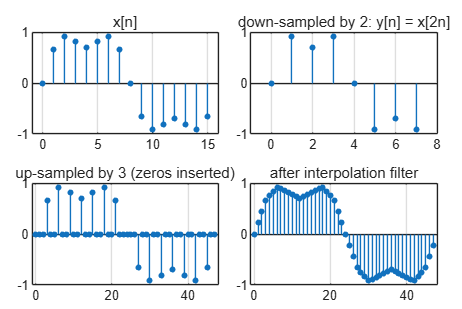

n = 0:15;
x = sin(2*pi*n/16) + 0.3*sin(2*pi*3*n/16);

M  = 2;  xd = x(1:M:end);                              % down-sample by 2: y[n] = x[2n]
L  = 3;  xu = zeros(1, L*numel(x));  xu(1:L:end) = x;  % up-sample by 3: insert zeros
h_lin = [1:L-1, L, L-1:-1:1] / L;                      % triangular kernel = linear interpolation
xi = conv(xu, h_lin, 'same');                          % interpolation = low-pass filtering

figure('Position', [100 100 900 600])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n, x, 'x[n]')
nexttile; stemplot(0:numel(xd)-1, xd, 'down-sampled by 2: y[n] = x[2n]')
nexttile; stemplot(0:numel(xu)-1, xu, 'up-sampled by 3 (zeros inserted)')
nexttile; stemplot(0:numel(xi)-1, xi, 'after interpolation filter')

Down-sampling without first removing the high frequencies causes **aliasing** (Section 10). Combining up-sampling by $L$ and down-sampling by $M$ changes the sample rate by the ratio $L/M$; we will use this for speed changes in Section 12.

## 5. Signal properties: symmetry, periodicity, energy and power

### 5.1 Even and odd parts

Every real signal splits uniquely into an even part and an odd part:


$$x_e[n] = \tfrac{1}{2}\big(x[n] + x[-n]\big), \qquad x_o[n] = \tfrac{1}{2}\big(x[n] - x[-n]\big)$$


n  = -15:15;
x  = 0.9.^n .* (n >= 0);                 % causal exponential: neither even nor odd
xr = fliplr(x);                          % x[-n]  (valid because n is symmetric about 0)
xe = (x + xr)/2;                         % even part
xo = (x - xr)/2;                         % odd part

checks = [isequal(xe, fliplr(xe)), isequal(xo, -fliplr(xo)), max(abs(x - (xe + xo))) < 1e-12]

checks = 1×3 logical array
   1   1   1


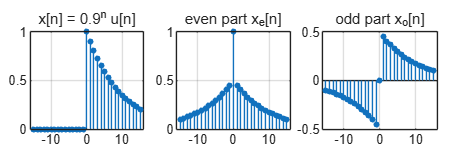


figure('Position', [100 100 900 300])
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n, x,  'x[n] = 0.9^n u[n]')
nexttile; stemplot(n, xe, 'even part x_e[n]')
nexttile; stemplot(n, xo, 'odd part x_o[n]')

For complex signals the counterparts are the conjugate-symmetric and conjugate-antisymmetric parts, built with $x^*[-n]$.

rng(5)
z    = randn(size(n)) + 1j*randn(size(n));
zcs  = (z + conj(fliplr(z)))/2;                 % conjugate-symmetric part
zcas = (z - conj(fliplr(z)))/2;                 % conjugate-antisymmetric part
errors = [max(abs(zcs - conj(fliplr(zcs)))), max(abs(zcas + conj(fliplr(zcas)))), max(abs(z - zcs - zcas))]

errors = 1.0e-15 *

         0         0    0.1241


### 5.2 Periodicity

A discrete sinusoid $\cos(2\pi f_0 n)$ is periodic **only if **$f_0$** is a rational number** $f_0 = p/q$, and then the fundamental period is $q$. A sum of periodic signals is periodic with the least common multiple of the periods. Two more facts that have no analogue in continuous time: $\omega_0$ and $\omega_0 + 2\pi$ give exactly the same sequence.

n    = 0:59;
xp1  = cos(2*pi*(1/12)*n);              % f0 = 1/12   -> period 12
xp2  = cos(2*pi*(3/8)*n);               % f0 = 3/8    -> period 8
xsum = xp1 + xp2;                       % period lcm(12,8) = 24
xp3  = cos(2*pi*(1/sqrt(50))*n);        % f0 irrational -> NOT periodic

isPer = @(x, N) all(abs(x(1+N:end) - x(1:end-N)) < 1e-9);
findN = @(x) find(arrayfun(@(N) isPer(x, N), 1:40), 1);     % smallest period up to 40 (empty = none)

N1   = findN(xp1)

N1 = 12

N2   = findN(xp2)

N2 = 8

Nsum = findN(xsum)

Nsum = 24

N3   = findN(xp3)                        % empty: not periodic


N3 =

  1×0 empty double row vector




alias_error = max(abs(cos(0.3*pi*n) - cos((0.3*pi + 2*pi)*n)))     % identical sequences

alias_error = 3.2338e-14

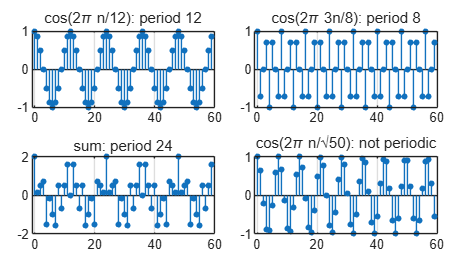


figure('Position', [100 100 900 500])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n, xp1,  'cos(2\pi n/12): period 12')
nexttile; stemplot(n, xp2,  'cos(2\pi 3n/8): period 8')
nexttile; stemplot(n, xsum, 'sum: period 24')
nexttile; stemplot(n, xp3,  'cos(2\pi n/\surd50): not periodic')

### 5.3 Energy, power and statistics

Energy $E = \sum |x[n]|^2$ is finite for decaying (transient) signals. Periodic and random signals have infinite energy but finite average power $P = \lim \frac{1}{N}\sum |x[n]|^2$. In audio, RMS level and crest factor are what people call *loudness* and *dynamics*.

rng(3)
% Energy signal: 0.95^n u[n]
k = 0:999;
E_num = sum((0.95.^k).^2);   E_theory = 1/(1 - 0.95^2);
fprintf('Energy of 0.95^n u[n]: numerical = %.4f, theory = %.4f\n', E_num, E_theory);

Energy of 0.95^n u[n]: numerical = 10.2564, theory = 10.2564



% Power signal: noisy sinusoid
n = 0:199;
s = 3*cos(2*pi*n/20);              % 10 whole periods, power A^2/2 = 4.5
v = 0.5*randn(size(n));            % noise, power 0.25
x = s + v;
P = mean(abs(x).^2);               % average power

Metrics = table(mean(x), sqrt(P), max(abs(x)), max(abs(x))/sqrt(P), 10*log10(P), ...
    'VariableNames', {'Mean', 'RMS', 'Peak', 'CrestFactor', 'Power_dB'})

Metrics = 1×5 table
      Mean        RMS       Peak     CrestFactor    Power_dB
    _________    ______    ______    ___________    ________

    0.0037738    2.1694    3.9811      1.8351        6.7268 



SNR_dB = 10*log10(mean(s.^2) / mean(v.^2))       % signal-to-noise ratio

SNR_dB = 12.7741

## 6. Convolution

### 6.1 Definition and index bookkeeping

The output of any linear time-invariant (LTI) system is the convolution of the input with the impulse response $h[n]$:


$$y[n] = (x * h)[n] = \sum_{k=-\infty}^{\infty} x[k]\,h[n-k]$$


If $x$ starts at $n_x$ and has $L_x$ samples and $h$ starts at $n_h$ with $L_h$ samples, then $y$ starts at $n_x + n_h$ and has $L_x + L_h - 1$ samples. The loop below is a literal implementation of the sum; `conv` gives the same numbers, and `conv_n` also returns the index vector.

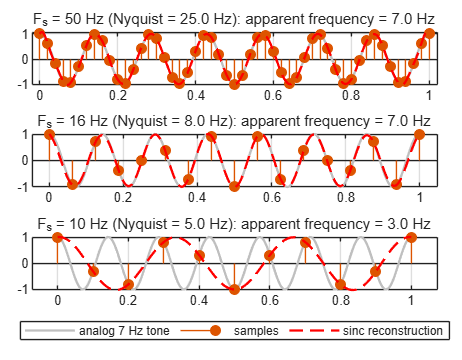

nx = 0:6;   x = [1 2 3 4 3 2 1];
nh = 0:3;   h = [1 1 1 1]/4;                  % 4-point moving average
[y, ny] = conv_n(x, nx, h, nh);

y_loop = zeros(size(ny));
for i = 1:numel(ny)                           % y[n] = sum_k x[k] h[n-k]
    for k = 1:numel(x)
        j = ny(i) - nx(k);                    % index into h
        if j >= nh(1) && j <= nh(end)
            y_loop(i) = y_loop(i) + x(k) * h(j - nh(1) + 1);
        end
    end
end
max_error = max(abs(y - y_loop))

figure('Position', [100 100 1000 300])
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact')

nexttile; stemplot(nx, x, 'x[n]')
nexttile; stemplot(nh, h, 'h[n]  (moving average)')
nexttile; stemplot(ny, y, 'y[n] = x[n] * h[n]')

### 6.2 Flip-and-slide

To compute one output sample $y[n_0]$: flip $h[k]$ into $h[-k]$, slide it to $h[n_0-k]$, multiply with $x[k]$ and add up all the products.

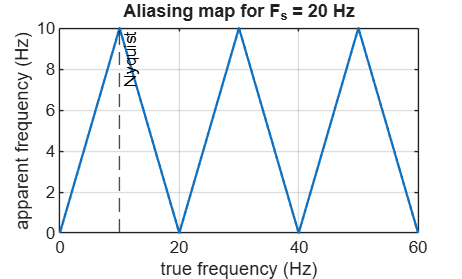

nx = 0:6;   x = [1 2 3 4 3 2 1];
nh = 0:3;   h = [1 1 1 1]/4;
k  = -4:10;
xk = xat(x, nx, k);                            % x[k] on the k-axis


figure('Position', [100 100 1000 650])
tiledlayout(3, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
for n0 = [1 3 5]
    hk = xat(h, nh, n0 - k);                   % h[n0-k]: flipped and slid to n0
    nexttile
    stem(k, xk, 'filled'); hold on; stem(k, hk, 'r'); hold off
    xlabel('k'); title(sprintf('x[k] (blue) and h[%d-k] (red)', n0), 'FontWeight', 'normal')
    nexttile
    stem(k, xk .* hk, 'filled'); xlabel('k')
    title(sprintf('products, sum = y[%d] = %.3f', n0, sum(xk .* hk)), 'FontWeight', 'normal')
end

### 6.3 Algebraic properties

Convolution is commutative, associative and distributive, $\delta[n]$ is the identity, and convolving with $\delta[n-n_0]$ is a pure delay. The table checks each property numerically with small integer sequences (errors should be exactly 0).

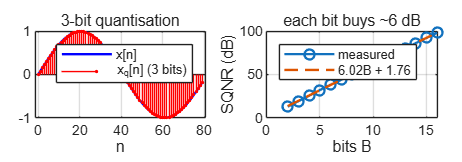

rng(2)
a = randi(5,1,5) - 3;   b = randi(5,1,4) - 3;   c = randi(5,1,3) - 3;   d = randi(5,1,4) - 3;

tests = {'commutative: a*b = b*a'; ...
         'associative: (a*b)*c = a*(b*c)'; ...
         'distributive: a*(b+d) = a*b + a*d'; ...
         'identity: a*delta[n] = a'; ...

         'delay: a*delta[n-2] = a[n-2]'};
maxError = [ max(abs(conv(a,b) - conv(b,a))); ...
             max(abs(conv(conv(a,b),c) - conv(a,conv(b,c)))); ...
             max(abs(conv(a,b+d) - (conv(a,b) + conv(a,d)))); ...
             max(abs(conv(a,1) - a)); ...
             max(abs(conv(a,[0 0 1]) - [0 0 a])) ];
table(tests, maxError, 'VariableNames', {'Property', 'MaxError'})

### 6.4 Convolution as a matrix product and as polynomial multiplication

Convolution is linear in $x$, so it can be written as a matrix product with a Toeplitz matrix. Multiplying polynomials is also a convolution of their coefficient lists. This is why $Y(z) = H(z)X(z)$ in the z-domain.

a = [1 2 3];   b = [1 -1 2 1];
T = toeplitz([a(:); zeros(numel(b)-1, 1)], [a(1), zeros(1, numel(b)-1)])   % convolution matrix of a
y_matrix = T * b(:);
y_conv   = conv(a, b).';
matrix_vs_conv = max(abs(y_matrix - y_conv))


Fs = 44100 Hz | duration = 8.00 s | 352800 samples | peak = 0.50 | RMS = -16.7 dBFS


% (1 + 2z^-1 + 3z^-2) * (1 - z^-1 + 2z^-2 + z^-3): coefficients are conv(a,b)
poly_coeffs = conv(a, b)

## 7. Correlation

Cross-correlation measures how similar $x$ is to a shifted copy of $y$. It is computed like a convolution with one signal folded, and it is the standard tool for **delay estimation** (radar, sonar, GPS) and for finding **periodicity**:


$$r_{xy}[m] = \sum_{n} x[n+m]\,y^*[n]$$


Below, a known random pulse `s` is buried in noise after an unknown delay. The peak of the correlation reveals the delay.

rng(3)

Original


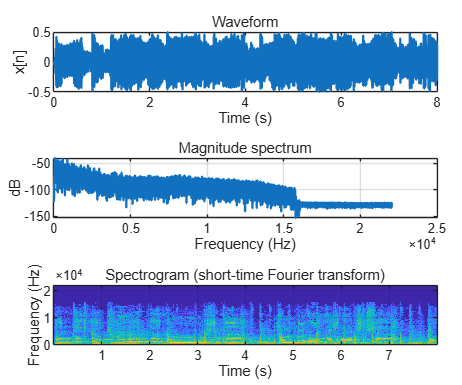

s   = randn(1, 100);                                        % transmitted pattern
D   = 37;                                                   % true delay in samples
rx  = [zeros(1,D), s, zeros(1,60)] + 0.5*randn(1, D+100+60);    % received: delayed + noisy

[r, lags] = xcorr_n(rx, s);
[~, imax] = max(r);
D_estimated = lags(imax)


figure('Position', [100 100 900 500])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stem(s, 'filled', 'MarkerSize', 2); title('transmitted pattern s[n]', 'FontWeight', 'normal')
nexttile; stem(rx, 'filled', 'MarkerSize', 2); title('received signal (delayed by 37 samples + noise)', 'FontWeight', 'normal')

ans = 10×2 table
    Gain_dB    Factor 
    _______    _______

      -40         0.01
      -20          0.1
      -12      0.25119
       -6      0.50119
       -3      0.70795
        0            1
        3       1.4125
        6       1.9953
       12       3.9811
       20           10


nexttile; plot(lags, r); xlabel('lag m'); title(sprintf('cross-correlation: peak at m = %d', lags(imax)), 'FontWeight', 'normal')

**Autocorrelation** ($y = x$) is symmetric and always peaks at lag 0. A periodic signal has peaks at every multiple of its period, even when it is hidden in noise, whereas white noise has a single spike at lag 0.

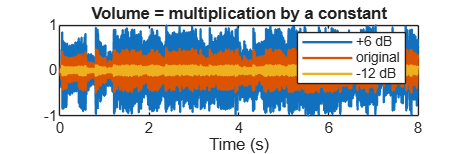

rng(4)
n     = 0:399;
sig   = cos(2*pi*n/25) + 0.8*randn(size(n));                % period 25, buried in noise
noise = randn(size(n));


[ra, la] = xcorr_n(sig, sig);
[rn, ln] = xcorr_n(noise, noise);

Original


+6 dB (louder)


figure('Position', [100 100 900 500])

-12 dB (quieter)


tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(n, sig);  title('noisy periodic signal', 'FontWeight', 'normal')
nexttile; plot(la, ra/max(ra)); xlim([-150 150]); title('autocorrelation: peaks every 25 samples', 'FontWeight', 'normal')
nexttile; plot(n, noise); title('white noise', 'FontWeight', 'normal')
nexttile; plot(ln, rn/max(rn)); xlim([-150 150]); title('autocorrelation: a single spike', 'FontWeight', 'normal')

peak before clipping = 5.00, samples clipped: 48.3 %


## 8. Discrete-time systems

### 8.1 Difference equations and basic building blocks

Every LTI system with a finite number of delays is described by a **difference equation**:


$$y[n] = \sum_{k=0}^{M} b_k\,x[n-k] \;-\; \sum_{k=1}^{N} a_k\,y[n-k]$$


In MATLAB, `filter(b, a, x)` runs this equation. Systems with only $b_k$ are **FIR** (finite impulse response); systems with feedback ($a_k \neq 0$) are **IIR**. The output of every LTI system equals the convolution of the input with its impulse response.

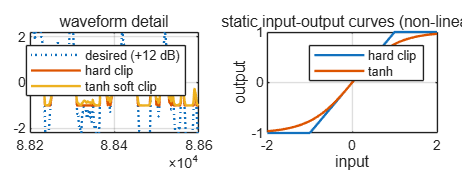

n = 0:29;
delta = double(n == 0);
h = filter(1, [1 -0.9], delta);              % impulse response of y[n] = 0.9y[n-1] + x[n]

rng(1)
x  = randn(size(n));
y1 = filter(1, [1 -0.9], x);                 % run the difference equation

y2 = conv(x, h);  y2 = y2(1:numel(x));       % ... or convolve with the impulse response
difference_eq_vs_convolution = max(abs(y1 - y2))

+12 dB with hard clipping (harsh)


A few classic building blocks, applied to a rectangular pulse.

n = 0:39;

+12 dB with soft saturation


x = double(n >= 5 & n < 15);                         % rectangular pulse

y_ma   = filter(ones(1,5)/5, 1, x);                  % 5-point moving average   y[n] = (1/5) sum x[n-k]
y_diff = filter([1 -1], 1, x);                       % first difference         y[n] = x[n] - x[n-1]
y_acc  = cumsum(x);                                  % accumulator (running sum) y[n] = sum_{k<=n} x[k]
y_ema  = filter(0.2, [1 -0.8], x);                   % exponential smoothing    y[n] = 0.8y[n-1] + 0.2x[n]
y_del  = filter([zeros(1,5) 1], 1, x);               % pure delay               y[n] = x[n-5]

figure('Position', [100 100 1000 500])
tiledlayout(2, 3, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stemplot(n, x,      'input pulse')
nexttile; stemplot(n, y_ma,   'moving average: smooths')
nexttile; stemplot(n, y_diff, 'first difference: finds edges')
nexttile; stemplot(n, y_acc,  'accumulator: integrates')
nexttile; stemplot(n, y_ema,  'exponential smoothing (IIR)')
nexttile; stemplot(n, y_del,  'delay by 5')

### 8.2 Impulse response and stability

An LTI system is **BIBO stable** when $\sum |h[n]| < \infty$. For a causal system this means all poles lie **inside the unit circle**. Watch how the pole location decides between decay, alternation, growth and oscillation.

n = 0:39;  delta = double(n == 0);
p_c = 0.9*exp(1j*pi/6);                                % complex pole pair
dens   = {[1 -0.9], [1 0.9], [1 -1.05], real(poly([p_c conj(p_c)]))};
labels = {'pole at +0.9', 'pole at -0.9', 'pole at +1.05', 'poles 0.9 e^{\pm j\pi/6}'};


RMS: original -16.7 dBFS -> compressed -12.6 dBFS (same peak)


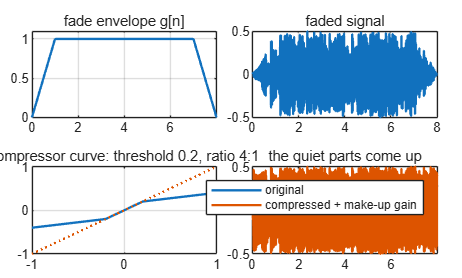

figure('Position', [100 100 900 500])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
for k = 1:4
    h = filter(1, dens{k}, delta);
    stable = max(abs(roots(dens{k}))) < 1;
    nexttile; stemplot(n, h, sprintf('%s: %s', labels{k}, ternary(stable, 'stable', 'UNSTABLE')));
end

### 8.3 Testing system properties numerically

A system is **linear** if $T\{a x_1 + b x_2\} = a\,T\{x_1\} + b\,T\{x_2\}$, **time-invariant** if delaying the input just delays the output, and **causal** if the output at $n$ never depends on inputs after $n$. The loop tests each property with random signals. A single failed test *proves* a property is missing; passing tests are evidence, not proof.

rng(4)

fade in / fade out


n  = 0:39;

compressed (louder quiet parts, same peak)


x1 = randn(size(n)) .* (n < 25);                    % random inputs that vanish near the end,
x2 = randn(size(n)) .* (n < 25);                    % so that shifting does not lose samples
a = 2;  b = -3;  kshift = 5;
shift = @(x, k) [zeros(1,k), x(1:end-k)];

Original


played at 1.5 Fs: 1.5x faster AND higher pitch


names   = {'y[n] = 0.9y[n-1] + x[n]'; 'y[n] = x[n]^2'; 'y[n] = n*x[n]'; ...

played at 0.6 Fs: slow motion AND lower pitch


           'y[n] = x[n] + x[n+1]'; 'y[n] = |x[n]|'};
systems = {@(x) filter(1,[1 -0.9],x); @(x) x.^2; @(x) n.*x; ...
           @(x) x + [x(2:end) 0]; @(x) abs(x)};

nS = numel(systems);

durations: original 8.00 s | fast 5.33 s | slow 13.33 s


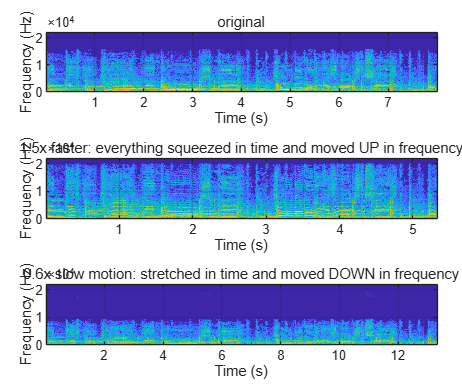

isLinear = false(nS,1);  isTI = false(nS,1);  isCausal = false(nS,1);
for i = 1:nS
    T = systems{i};
    isLinear(i) = norm(T(a*x1 + b*x2) - (a*T(x1) + b*T(x2))) < 1e-9;
    isTI(i)     = norm(T(shift(x1,kshift)) - shift(T(x1),kshift)) < 1e-9;
    x3 = x1;  x3(n >= 20) = randn(1, sum(n >= 20));     % change only the FUTURE of n = 19

    y1 = T(x1);  y3 = T(x3);
    isCausal(i) = norm(y1(n < 20) - y3(n < 20)) < 1e-9;

resampled 1.5x faster


end

resampled 0.6x (slow motion)


table(names, isLinear, isTI, isCausal, 'VariableNames', {'System', 'Linear', 'TimeInvariant', 'Causal'})

### 8.4 Smoothing and denoising filters

Linear filters (moving average, exponential smoothing) reduce Gaussian noise but blur edges and smear spikes. A **median filter** is *non-linear*: it removes isolated spikes and keeps edges sharp. It is not an LTI system, so there is no impulse response and no frequency response.

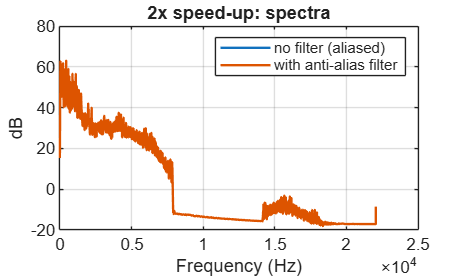

rng(6)
n     = 0:199;
clean = double(n >= 60 & n < 140);                    % rectangular pulse
xs    = clean + 0.15*randn(size(n));                  % Gaussian noise
idx   = randperm(200, 8);
xs(idx) = xs(idx) + 2*sign(randn(1,8));               % plus a few impulsive spikes

M     = 9;

y_ma  = conv(xs, ones(1,M)/M, 'same');                % linear: moving average
y_ema = filter(0.2, [1 -0.8], xs);                    % linear: exponential smoothing (causal, delayed)

2x faster, NO anti-alias filter


y_med = medfilt_n(xs, M);                             % non-linear: median filter

2x faster, with anti-alias filter



figure('Position', [100 100 900 700])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(n, xs); title('noisy pulse with spikes', 'FontWeight', 'normal')
nexttile; plot(n, y_ma); hold on; plot(n, clean, 'k:'); hold off

durations: original 8.00 s | L/M=2/3 5.33 s | L/M=4/3 10.67 s


title('9-point moving average: spikes are smeared, edges blurred', 'FontWeight', 'normal')
nexttile; plot(n, y_ema); hold on; plot(n, clean, 'k:'); hold off

L/M = 2/3 : 1.5x faster


title('exponential smoothing: also lags behind the signal', 'FontWeight', 'normal')

L/M = 4/3 : 0.75x speed


nexttile; plot(n, y_med); hold on; plot(n, clean, 'k:'); hold off
title('9-point median: spikes gone, edges preserved', 'FontWeight', 'normal')

## 9. Frequency-domain view: DFT, FFT and frequency response

### 9.1 The DFT by definition versus the FFT

The $N$-point DFT turns $N$ samples into $N$ complex frequency samples. The FFT is simply a fast algorithm for the same numbers (about $N\log_2 N$ operations instead of $N^2$).


$$X[k] = \sum_{n=0}^{N-1} x[n]\,e^{-j2\pi kn/N}, \qquad x[n] = \frac{1}{N}\sum_{k=0}^{N-1} X[k]\,e^{\,j2\pi kn/N}$$


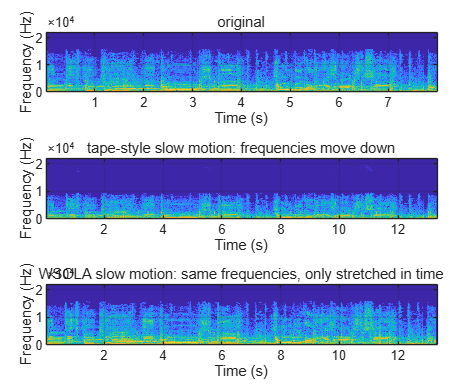

N  = 8;   nn = 0:N-1;
x  = cos(2*pi*nn/N) + 0.5*sin(2*pi*3*nn/N);

W     = exp(-2j*pi*(0:N-1).'*(0:N-1)/N);       % DFT matrix: X = W x
X_def = W * x(:);                              % DFT straight from the definition
X_fft = fft(x);                                % FFT
definition_vs_fft = max(abs(X_def(:) - X_fft(:)))

figure('Position', [100 100 900 300])

tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stem(nn, abs(X_fft), 'filled'); xlabel('k'); title('|X[k]|: cos gives k = 1, 7; sin gives k = 3, 5', 'FontWeight', 'normal')

Original


nexttile; stem(nn, angle(X_fft)/pi, 'filled'); xlabel('k'); ylabel('\angle X[k] / \pi'); title('phase', 'FontWeight', 'normal')

WSOLA 0.6x: slow motion, pitch unchanged


Speed comparison for $N = 2048$ (the matrix product costs $N^2$ complex multiplications).

Nt = 2048;   xt = randn(Nt, 1);

WSOLA 1.5x: faster, pitch unchanged


Wt = exp(-2j*pi*(0:Nt-1).'*(0:Nt-1)/Nt);
tic; Xd = Wt * xt; t_matrix = toc;
tic; Xf = fft(xt); t_fft    = toc;
fprintf('matrix DFT: %.5f s   FFT: %.6f s   (max difference %.1e)\n', t_matrix, t_fft, max(abs(Xd - Xf)));

### 9.2 Reading a spectrum on a frequency axis in Hz

Bin $k$ corresponds to the frequency $k F_s/N$. For a real signal the spectrum is conjugate-symmetric, so only the first half carries new information. Scaling by $2/N$ turns the height of a peak into the amplitude of the sinusoid.

Fs = 1000;  N = 200;  n = 0:N-1;  t = n/Fs;

ans = 9×2 table
    Semitones    FrequencyRatio
    _________    ______________

       -12              0.5    
        -7          0.66742    
        -5          0.74915    
        -2           0.8909    
         2           1.1225    
         4           1.2599    
         5           1.3348    
         7           1.4983    
        12                2    


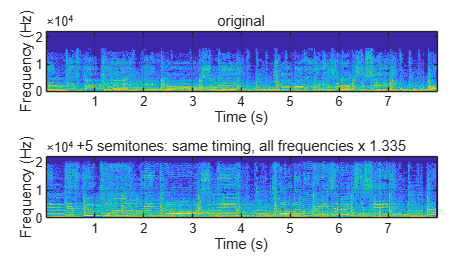

x  = 1.0*sin(2*pi*50*t) + 0.5*sin(2*pi*120*t);
X  = fft(x);
f  = (0:N-1) * Fs/N;                           % frequency of each bin in Hz
A  = 2*abs(X(1:N/2+1)) / N;                    % single-sided amplitude spectrum
f2 = (-N/2:N/2-1) * Fs/N;                      % two-sided axis for fftshift

figure('Position', [100 100 900 650])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(t, x); xlabel('t (s)'); title('x(t) = 1.0 sin(2\pi 50 t) + 0.5 sin(2\pi 120 t), F_s = 1 kHz', 'FontWeight', 'normal')

nexttile; stem(f(1:N/2+1), A, 'filled'); xlabel('f (Hz)'); ylabel('amplitude'); title('single-sided amplitude spectrum: peaks 1.0 and 0.5', 'FontWeight', 'normal')
nexttile; plot(f2, fftshift(abs(X))/N); xlabel('f (Hz)'); title('two-sided spectrum after fftshift: every real tone appears at +f and -f', 'FontWeight', 'normal')

+5 semitones


### 9.3 Zero-padding, spectral leakage and windows

A sinusoid whose frequency falls exactly on a DFT bin gives one clean line. If it falls *between* bins, its energy leaks into all bins because the signal was implicitly multiplied by a rectangular window. A smooth window (Hann) trades a wider main lobe for much lower leakage. **Zero-padding** does not add resolution, it only interpolates the spectrum so you can see its true shape.

Fs = 1000;  N = 200;  n = 0:N-1;  t = n/Fs;

-5 semitones


xa = sin(2*pi*50.0*t);                  % 50 Hz   -> exactly on bin 10 (resolution Fs/N = 5 Hz)

original + major-third harmony


xb = sin(2*pi*52.5*t);                  % 52.5 Hz -> between bins 10 and 11
wh = 0.5 - 0.5*cos(2*pi*n/N);           % Hann window
wr = ones(1, N);                        % rectangular window

Nfft = 4096;  fz = (0:Nfft-1) * Fs/Nfft;                          % zero-padded FFT axis
spec = @(x, w) 20*log10(2*abs(fft(x.*w, Nfft))/sum(w) + 1e-6);    % dB, 0 dB = unit-amplitude tone
fb   = (0:N-1) * Fs/N;                                            % plain N-point DFT bins

figure
plot(fz, spec(xa,wr), fz, spec(xb,wr), fz, spec(xb,wh)); hold on
stem(fb, 20*log10(2*abs(fft(xb))/N + 1e-6), 'filled', 'MarkerSize', 3, 'BaseValue', -100, 'Color', [0.3 0.3 0.3]); hold off
xlim([0 150]); ylim([-100 5]); xlabel('f (Hz)'); ylabel('dB')
legend('50 Hz, rectangular', '52.5 Hz, rectangular', '52.5 Hz, Hann', 'DFT bins of 52.5 Hz', 'Location', 'northeast')
title('Leakage and windowing (zero-padded to 4096 points)')

### 9.4 Properties of the DFT

Each property below is verified numerically. The maximum error should be around $10^{-15}$ (rounding only).

rng(7)
N = 8;  x = randn(1, N);  X = fft(x);
m = 3;

err_shift   = max(abs(fft(circshift(x, m)) - X .* exp(-2j*pi*(0:N-1)*m/N)));   % circular shift <-> linear phase
err_parseval = abs(sum(abs(x).^2) - sum(abs(X).^2)/N);                         % energy is preserved
err_conjsym  = max(abs(X(2:end) - conj(X(end:-1:2))));                         % real x -> X[N-k] = X*[k]

a = randn(1, 50);  b = randn(1, 20);
Nf = numel(a) + numel(b) - 1;
err_conv = max(abs(ifft(fft(a,Nf) .* fft(b,Nf)) - conv(a,b)));                 % multiply spectra = convolve

property = {'Circular shift'; 'Parseval'; 'Conjugate symmetry'; 'Convolution theorem'};
maxError = [err_shift; err_parseval; err_conjsym; err_conv];
table(property, maxError)

**Circular versus linear convolution.** Multiplying $N$-point DFTs gives *circular* convolution. If $N$ is shorter than $L_x + L_h - 1$ the tail wraps around and overlaps the beginning (time-domain aliasing). Zero-pad to at least $L_x + L_h - 1$ to get the linear convolution.

a = [1 2 3 4];   b = [1 0 1];
linear       = conv(a, b)                                      % length 6
circular_N4  = real(ifft(fft(a, 4) .* fft(b, 4)))              % length 4: tail wrapped around
circular_N6  = real(ifft(fft(a, 6) .* fft(b, 6)))              % zero-padded to 6: equals linear

### 9.5 Frequency response of an LTI system

An input $e^{j\omega n}$ passes through an LTI system unchanged except for a complex factor, the **frequency response** $H(e^{j\omega})$ (the DTFT of $h[n]$). So a sinusoid in gives a sinusoid of the same frequency out, scaled by $|H|$ and shifted by $\angle H$.


$$H(e^{j\omega}) = \sum_n h[n]\,e^{-j\omega n} = \frac{\sum_k b_k e^{-j\omega k}}{1 + \sum_k a_k e^{-j\omega k}}$$


w      = linspace(-pi, pi, 1001);                 % digital frequency axis
h_ma   = ones(1,5)/5;
H_ma   = freqz_n(h_ma, 1, w);                     % moving average  : low-pass
H_diff = freqz_n([1 -1], 1, w);                   % first difference: high-pass
H_ema  = freqz_n(0.2, [1 -0.8], w);               % exponential smoothing: low-pass

figure('Position', [100 100 900 500])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(w/pi, abs(H_ma), w/pi, abs(H_diff), w/pi, abs(H_ema))
xlabel('\omega / \pi'); ylabel('|H(e^{j\omega})|'); legend('5-pt moving average', 'first difference', 'exponential smoothing')
nexttile; plot(w/pi, angle(H_ma)/pi, w/pi, angle(H_diff)/pi, w/pi, angle(H_ema)/pi)
xlabel('\omega / \pi'); ylabel('phase / \pi'); title('phase response', 'FontWeight', 'normal')

Check the eigenfunction property: feed a cosine through the moving average and compare with the prediction $|H|\cos(\omega_0 n + \angle H)$.

w0 = pi/6;   n = 0:79;
x  = cos(w0*n);
y  = filter(h_ma, 1, x);
H0 = freqz_n(h_ma, 1, w0);
y_pred = abs(H0) * cos(w0*n + angle(H0));
steady = 10:numel(n);                                     % skip the start-up transient
error_after_transient = max(abs(y(steady) - y_pred(steady)))

figure
stem(n, x, 'Color', [0.6 0.6 0.6]); hold on; stem(n, y, 'filled'); plot(n, y_pred, 'r'); hold off
legend('input cos(\omega_0 n)', 'output y[n]', 'prediction |H| cos(\omega_0 n + \angle H)'); xlabel('n')
title(sprintf('|H(\\omega_0)| = %.3f: same frequency, smaller amplitude, delayed', abs(H0)))

## 10. Sampling, aliasing and quantisation

### 10.1 Sampling and aliasing

A tone of frequency $f_0$ sampled at $F_s$ can only be reconstructed when $F_s > 2f_0$ (Nyquist). Otherwise it masquerades as a lower frequency, the **alias**:


$$f_{\rm apparent} = \left| f_0 - F_s \cdot \mathrm{round}(f_0/F_s) \right|$$


Below, a 7 Hz tone is sampled at 50 Hz (fine), 16 Hz (barely fine) and 10 Hz (aliased to 3 Hz). The red curve is ideal band-limited (sinc) reconstruction from the samples.

f0 = 7;                                          % analog tone in Hz
tt = 0:1e-4:1;   xa = cos(2*pi*f0*tt);           % the "analog" signal
tr = 0:1e-3:1;                                   % reconstruction time axis

figure('Position', [100 100 900 700])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
for Fs_k = [50 16 10]
    n  = 0:Fs_k;   Ts = 1/Fs_k;
    xn = cos(2*pi*f0*n*Ts);                                  % the samples
    xr = sincf((tr(:) - n*Ts)/Ts) * xn(:);                   % sum of x[n] sinc((t - nTs)/Ts)
    f_apparent = abs(f0 - Fs_k*round(f0/Fs_k));
    nexttile
    plot(tt, xa, 'Color', [0.75 0.75 0.75]); hold on
    stem(n*Ts, xn, 'filled'); plot(tr, xr, 'r--'); hold off
    title(sprintf('F_s = %d Hz (Nyquist = %.1f Hz): apparent frequency = %.1f Hz', Fs_k, Fs_k/2, f_apparent), 'FontWeight', 'normal')
end
legend('analog 7 Hz tone', 'samples', 'sinc reconstruction', 'Location', 'southoutside', 'Orientation', 'horizontal')

The map from true to apparent frequency is a triangle wave that folds back at multiples of $F_s/2$. This is why audio is low-pass filtered *before* it is down-sampled (anti-alias filter).

Fs = 20;
f_true = 0:0.25:60;
f_app  = abs(f_true - Fs*round(f_true/Fs));

figure
plot(f_true, f_app); xline(Fs/2, 'k--', 'Nyquist'); xlabel('true frequency (Hz)'); ylabel('apparent frequency (Hz)')
title('Aliasing map for F_s = 20 Hz')

### 10.2 Quantisation

Storing a sample with $B$ bits rounds it to one of $2^B$ levels. The error behaves like noise, and every extra bit improves the signal-to-quantisation-noise ratio by about 6 dB:


$$\mathrm{SQNR} \approx 6.02\,B + 1.76 \ \text{dB} \quad \text{(full-scale sinusoid)}$$


n = 0:9999;   x = 0.99*sin(2*pi*0.0123*n);
bits = 2:16;  sqnr = zeros(size(bits));
for i = 1:numel(bits)
    e = x - quantize(x, bits(i));
    sqnr(i) = 10*log10(mean(x.^2) / mean(e.^2));
end

figure('Position', [100 100 1000 350])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; k = 1:80;
plot(n(k), x(k), 'b-'); hold on; stem(n(k), quantize(x(k), 16), 'r.'); hold off
legend('x[n]', 'x_q[n] (3 bits)'); xlabel('n'); title('3-bit quantisation', 'FontWeight', 'normal')
nexttile; plot(bits, sqnr, 'o-', bits, 6.02*bits + 1.76, '--')
xlabel('bits B'); ylabel('SQNR (dB)'); legend('measured', '6.02B + 1.76', 'Location', 'northwest'); title('each bit buys ~6 dB', 'FontWeight', 'normal')

## 11. Filter design and the z-plane

### 11.1 FIR filters by windowed sinc

The ideal low-pass filter has a sinc-shaped impulse response of infinite length. Truncating it with a Hamming window gives a practical linear-phase FIR filter. A high-pass filter follows by *spectral inversion* ($\delta[n-M] - h_{lp}[n]$) and a band-pass filter by subtracting two low-pass filters.

Fs = 1000;   N = 101;                                       % N taps (odd)
h_lp = lowpass_fir(100/Fs, N);                              % low-pass, cut-off 100 Hz
h_hp = -h_lp;  h_hp((N+1)/2) = h_hp((N+1)/2) + 1;           % high-pass by spectral inversion
h_bp = lowpass_fir(200/Fs, N) - lowpass_fir(100/Fs, N);     % band-pass 100-200 Hz

w = linspace(0, pi, 2048);   f = w/(2*pi)*Fs;
figure('Position', [100 100 1000 350])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stem(0:N-1, h_lp, 'filled', 'MarkerSize', 3); xlabel('n'); title('impulse response of the low-pass filter', 'FontWeight', 'normal')
nexttile
plot(f, 20*log10(abs(freqz_n(h_lp,1,w)) + 1e-6)); hold on
plot(f, 20*log10(abs(freqz_n(h_hp,1,w)) + 1e-6))
plot(f, 20*log10(abs(freqz_n(h_bp,1,w)) + 1e-6)); hold off
ylim([-80 5]); xlabel('f (Hz)'); ylabel('dB'); legend('low-pass', 'high-pass', 'band-pass'); title('magnitude responses', 'FontWeight', 'normal')

% Apply the three filters to a mixture of 20, 150 and 300 Hz
t = (0:999)/Fs;
x = sin(2*pi*20*t) + sin(2*pi*150*t) + sin(2*pi*300*t);
y_lp = conv(x, h_lp, 'same');   y_hp = conv(x, h_hp, 'same');   y_bp = conv(x, h_bp, 'same');

figure('Position', [100 100 900 600])
tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(t(1:300), x(1:300));    title('input: 20 + 150 + 300 Hz', 'FontWeight', 'normal')
nexttile; plot(t(1:300), y_lp(1:300)); title('low-pass 100 Hz: only 20 Hz remains', 'FontWeight', 'normal')
nexttile; plot(t(1:300), y_hp(1:300)); title('high-pass 100 Hz: 150 + 300 Hz remain', 'FontWeight', 'normal')
nexttile; plot(t(1:300), y_bp(1:300)); title('band-pass 100-200 Hz: only 150 Hz remains', 'FontWeight', 'normal'); xlabel('t (s)')

### 11.2 IIR notch filter and the pole-zero plot

The transfer function $H(z) = B(z)/A(z)$ is the z-transform of $h[n]$. Its **zeros** kill frequencies, its **poles** create resonances, and the frequency response is $H(z)$ evaluated on the unit circle. A notch filter puts zeros *on* the unit circle at the unwanted frequency and poles just *inside* it, so it removes one tone (mains hum!) and leaves everything else nearly untouched.


$$H(z) = \frac{1 - 2\cos\omega_0\,z^{-1} + z^{-2}}{1 - 2r\cos\omega_0\,z^{-1} + r^2 z^{-2}}$$


Fs = 1000;  f0 = 50;  w0 = 2*pi*f0/Fs;  r = 0.95;
b = [1, -2*cos(w0), 1];                       % zeros at exp(+-j w0): on the unit circle
a = [1, -2*r*cos(w0), r^2];                   % poles at r*exp(+-j w0): just inside
zz = roots(b);   pp = roots(a);

w = linspace(0, pi, 2048);   f = w/(2*pi)*Fs;
H = freqz_n(b, a, w);

t     = (0:999)/Fs;
clean = sin(2*pi*5*t) + 0.4*sin(2*pi*13*t);       % wanted signal
x     = clean + 0.8*sin(2*pi*50*t);               % plus 50 Hz hum
y     = filter(b, a, x);                          % notch filter removes the hum

th = linspace(0, 2*pi, 400);
figure('Position', [100 100 1000 600])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile
plot(cos(th), sin(th), 'k:'); hold on
plot(real(zz), imag(zz), 'o', 'MarkerSize', 9); plot(real(pp), imag(pp), 'x', 'MarkerSize', 9); hold off
axis equal; xlabel('Re'); ylabel('Im'); legend('unit circle', 'zeros', 'poles'); title('pole-zero plot', 'FontWeight', 'normal')
nexttile; plot(f, 20*log10(abs(H) + 1e-6)); ylim([-60 5]); xlabel('f (Hz)'); ylabel('dB'); title('notch at 50 Hz', 'FontWeight', 'normal')
nexttile([1 2])
plot(t, x, 'Color', [0.7 0.7 0.7]); hold on; plot(t, y, 'b', t, clean, 'r:'); hold off
xlabel('t (s)'); legend('with hum', 'notch filter output', 'wanted signal'); title('hum removal (short start-up transient)', 'FontWeight', 'normal')

## 12. Application: processing real music

Music is just a long discrete-time signal: The mp3 file is typically sampled with 44.1 kHz sampling frequency. Every operation in the previous sections applies directly. Below, each classic audio effect is shown next to the DSP idea it really is.

### 12.1 Load the music and look at it

**Run this section first.** To use your own song instead, uncomment the `audioread` lines. The signal is normalised to a peak of 0.5 (−6 dBFS) so that gain experiments have headroom before clipping at ±1.

% x = y(:);                            % column vector
% x = x(1:min(end, 6*Fs));             % keep the first 6 seconds
% x = 0.5 * x / max(abs(x));           % normalise: peak = 0.5 (-6 dBFS)

% ---- to use your own music, uncomment these lines ----
[x, Fs] = audioread('Justin Bieber - Ghost.mp3');   x = mean(x, 2);        % stereo -> mono
x = x(1:min(end, 8*Fs));   x = 0.5 * x / max(abs(x));

N = numel(x);   t = (0:N-1).' / Fs;
fprintf('Fs = %d Hz | duration = %.2f s | %d samples | peak = %.2f | RMS = %.1f dBFS\n', ...
        Fs, N/Fs, N, max(abs(x)), 20*log10(sqrt(mean(x.^2))));

setappdata(0, 'hearWait', true);     % true: wait for each clip to finish; false: return immediately
hear(x, Fs, 'Original');

Nh = floor(N/2);   f = (0:Nh-1) * Fs/N;   X = fft(x);
figure('Position', [100 100 900 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(t, x); xlabel('Time (s)'); ylabel('x[n]'); title('Waveform', 'FontWeight', 'normal')
nexttile; plot(f, 20*log10(abs(X(1:Nh))/N + 1e-9)); xlabel('Frequency (Hz)'); ylabel('dB'); title('Magnitude spectrum', 'FontWeight', 'normal')
nexttile; plotspec(x, Fs, 'Spectrogram (short-time Fourier transform)')

### 12.2 Volume: turning it up and down

Volume is multiplication by a constant, $y[n] = g\,x[n]$. Loudness is perceived roughly logarithmically, so gain is quoted in decibels: $g = 10^{G_{dB}/20}$. **+6 dB doubles the amplitude, −6 dB halves it, −20 dB is a factor of 10.**

dB = [-40 -20 -12 -6 -3 0 3 6 12 20].';
table(dB, 10.^(dB/20), 'VariableNames', {'Gain_dB', 'Factor'})

x_up   = 10^(  6/20) * x;            % +6 dB  : amplitude x 2    (peak 0.5 -> 1.0)
x_down = 10^(-12/20) * x;            % -12 dB : amplitude x 0.25

figure('Position', [100 100 900 300])
plot(t, x_up, t, x, t, x_down); xlabel('Time (s)'); legend('+6 dB', 'original', '-12 dB'); title('Volume = multiplication by a constant')

hear(x,      Fs, 'Original');
hear(x_up,   Fs, '+6 dB (louder)');
hear(x_down, Fs, '-12 dB (quieter)');

**Too much gain: clipping.** A DAC cannot output more than ±1. Samples beyond full scale are flattened (hard clipping), which creates harmonic distortion. A smooth saturation such as `tanh` bends the peaks instead of chopping them, which sounds gentler.

x_big  = 10^(20/20) * x;                    % +12 dB: the peak would be about 2.0
x_hard = max(min(x_big, 1), -1);            % hard clipping at +-1
x_soft = tanh(x_big);                       % soft saturation
fprintf('peak before clipping = %.2f, samples clipped: %.1f %%\n', max(abs(x_big)), 100*mean(abs(x_big) > 1));

seg = round(2*Fs) + (1:400);                % a short piece of the waveform
figure('Position', [100 100 900 350])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(seg, x_big(seg), ':', seg, x_hard(seg), seg, x_soft(seg)); ylim([-2.2 2.2])
legend('desired (+12 dB)', 'hard clip', 'tanh soft clip'); title('waveform detail', 'FontWeight', 'normal')
nexttile; v = linspace(-2, 2, 401); plot(v, max(min(v,1),-1), v, tanh(v)); grid on
xlabel('input'); ylabel('output'); title('static input-output curves (non-linear!)', 'FontWeight', 'normal'); legend('hard clip', 'tanh')

hear(x_hard, Fs, '+12 dB with hard clipping (harsh)');
hear(x_soft, Fs, '+12 dB with soft saturation');

### 12.3 Fade in/out, normalisation and compression

A **fade** is multiplication by a slowly varying gain $g[n]$ (an envelope). **Normalisation** picks one constant gain to hit a target peak or RMS level. A **compressor** is a non-linear gain: levels above a threshold are reduced by a ratio, and then make-up gain brings the whole signal back up, so quiet parts become louder without clipping.

% Linear fade-in and fade-out (1 s each)
nf  = round(1*Fs);
env = ones(N, 1);
env(1:nf)         = linspace(0, 1, nf).';
env(end-nf+1:end) = linspace(1, 0, nf).';
x_fade = x .* env;

% Peak and RMS normalisation
x_peak = 0.99 * x / max(abs(x));                         % peak -> just below full scale
x_rms  = 10^(-20/20) / sqrt(mean(x.^2)) * x;             % RMS  -> -20 dBFS

% Static compressor + make-up gain
thr = 0.2;   ratio = 4;
comp   = @(v) sign(v) .* (min(abs(v), thr) + max(abs(v) - thr, 0)/ratio);
x_comp = comp(x);
x_comp = x_comp * (max(abs(x)) / max(abs(x_comp)));      % make-up gain restores the original peak
fprintf('RMS: original %.1f dBFS -> compressed %.1f dBFS (same peak)\n', ...
        20*log10(sqrt(mean(x.^2))), 20*log10(sqrt(mean(x_comp.^2))));

figure('Position', [100 100 1000 600])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(t, env); ylim([0 1.1]); title('fade envelope g[n]', 'FontWeight', 'normal')
nexttile; plot(t, x_fade); title('faded signal', 'FontWeight', 'normal')
nexttile; v = linspace(-1, 1, 401); plot(v, comp(v), v, v, ':'); grid on; title('compressor curve: threshold 0.2, ratio 4:1', 'FontWeight', 'normal')
nexttile; plot(t, x, t, x_comp); legend('original', 'compressed + make-up gain'); title('the quiet parts come up', 'FontWeight', 'normal')

hear(x_fade, Fs, 'fade in / fade out');
hear(x_comp, Fs, 'compressed (louder quiet parts, same peak)');

### 12.4 Speed: faster and slow motion (tape-style)

**Idea 1: change the playback clock.** Play the *same samples* at a different rate. Twice the rate is twice as fast and one octave higher; half the rate is slow motion and one octave lower. This is exactly what a vinyl record or a tape machine does.

hear(x, Fs,     'Original');
hear(x, 1.5*Fs, 'played at 1.5 Fs: 1.5x faster AND higher pitch');
hear(x, 0.6*Fs, 'played at 0.6 Fs: slow motion AND lower pitch');

**Idea 2: change the data.** To get the same effect at the normal sample rate, read the signal at fractional positions $1, 1+r, 1+2r, \dots$ and interpolate. This is $y[n] = x(rn)$, the general time-scaling of Section 4.1. For $r>1$ (speed-up) we must first low-pass filter, otherwise frequencies above $F_s/(2r)$ alias (Section 10.1).

y_fast = change_speed(x, 1.5);            % read positions 1, 2.5, 4, ...
y_slow = change_speed(x, 0.6);            % read positions 1, 1.6, 2.2, ...
fprintf('durations: original %.2f s | fast %.2f s | slow %.2f s\n', N/Fs, numel(y_fast)/Fs, numel(y_slow)/Fs);

figure('Position', [100 100 900 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plotspec(x,      Fs, 'original')
nexttile; plotspec(y_fast, Fs, '1.5x faster: everything squeezed in time and moved UP in frequency')
nexttile; plotspec(y_slow, Fs, '0.6x slow motion: stretched in time and moved DOWN in frequency')

hear(y_fast, Fs, 'resampled 1.5x faster');
hear(y_slow, Fs, 'resampled 0.6x (slow motion)');

**Why the anti-alias filter matters.** Same 2x speed-up, with and without the low-pass filter. Without it, the components between 2 and 4 kHz fold back into the audible band as inharmonic garbage.

y2_alias = change_speed(x, 2, false);     % no anti-alias filter
y2_clean = change_speed(x, 2, true);      % with anti-alias filter

L2 = numel(y2_alias);  Lh = floor(L2/2);  fa = (0:Lh-1) * Fs/L2;
sm  = @(v) conv(20*log10(abs(v(1:Lh)) + 1e-9), ones(64,1)/64, 'same');    % smoothed spectrum in dB
figure
plot(fa, sm(fft(y2_alias)), fa, sm(fft(y2_clean)));
xlabel('Frequency (Hz)'); ylabel('dB'); legend('no filter (aliased)', 'with anti-alias filter'); title('2x speed-up: spectra')

hear(y2_alias, Fs, '2x faster, NO anti-alias filter');
hear(y2_clean, Fs, '2x faster, with anti-alias filter');

**Idea 3: rational sample-rate conversion.** Up-sample by $L$, low-pass filter, down-sample by $M$. The signal now has $L/M$ times as many samples, so playing it at $F_s$ changes the speed by the factor $M/L$. This is the integer-arithmetic version of the same operation (Section 4.3).

y_23 = resamp_LM(x, 2, 3);                % L/M = 2/3 : 2/3 as many samples -> 1.5x faster
y_43 = resamp_LM(x, 4, 3);                % L/M = 4/3 : 4/3 as many samples -> 0.75x speed (slower)
fprintf('durations: original %.2f s | L/M=2/3 %.2f s | L/M=4/3 %.2f s\n', N/Fs, numel(y_23)/Fs, numel(y_43)/Fs);

hear(y_23, Fs, 'L/M = 2/3 : 1.5x faster');
hear(y_43, Fs, 'L/M = 4/3 : 0.75x speed');

### 12.5 Speed without changing the pitch (time-stretching)

Tape-style speed change couples tempo and pitch. To change **tempo only**, use WSOLA (Waveform-Similarity Overlap-Add):

- Cut the signal into overlapping Hann-windowed frames of about 60 ms.

- Take input frames at a hop $H_a = \text{rate}\cdot H_s$, but write them to the output with a fixed hop $H_s$. This changes the tempo.

- Nudge each input frame by a few samples so that it best matches (maximum normalised cross-correlation) the natural continuation of the previous frame. This keeps the waveforms in phase and avoids warbling.

- Overlap-add the frames.

y_fast_p = wsola(x, Fs, 1.5);             % 1.5x faster, same pitch
y_slow_p = wsola(x, Fs, 0.6);             % 0.6x slower, same pitch
y_slow_t = change_speed(x, 0.6);          % tape-style slow motion, for comparison

figure('Position', [100 100 900 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plotspec(x,        Fs, 'original')
nexttile; plotspec(y_slow_t, Fs, 'tape-style slow motion: frequencies move down')
nexttile; plotspec(y_slow_p, Fs, 'WSOLA slow motion: same frequencies, only stretched in time')

hear(x,        Fs, 'Original');
hear(y_slow_p, Fs, 'WSOLA 0.6x: slow motion, pitch unchanged');
hear(y_fast_p, Fs, 'WSOLA 1.5x: faster, pitch unchanged');

### 12.6 Pitch shifting

Pitch shifting is the mirror image: change the pitch and keep the duration. **Time-stretch by **$\rho$** (pitch unchanged), then speed up by **$\rho$** (tape-style)**. The pitch goes up by $\rho$ and the duration returns to the original. For $k$ semitones, $\rho = 2^{k/12}$.

semitones = [-12 -7 -5 -2 2 4 5 7 12].';
table(semitones, 2.^(semitones/12), 'VariableNames', {'Semitones', 'FrequencyRatio'})

x_pitch_up   = pitch_shift(x, Fs, +10);                  % up a perfect fourth, same duration
x_pitch_down = pitch_shift(x, Fs, -5);                  % down a perfect fourth
x_harmony    = nrm(x + pitch_shift(x, Fs, +7));         % add a voice a major third above

figure('Position', [100 100 900 500])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plotspec(x,            Fs, 'original')
nexttile; plotspec(x_pitch_up,   Fs, '+5 semitones: same timing, all frequencies x 1.335')

hear(x_pitch_up,   Fs, '+5 semitones');
hear(x_pitch_down, Fs, '-5 semitones');
hear(x_harmony,    Fs, 'original + major-third harmony');

### 12.7 Time-varying speed: tape stop and vibrato

Generalise time scaling to $y[n] = x(\tau[n])$ where the read position $\tau[n]$ is any increasing curve. A constant slope gives a speed change, a slope that decays to zero gives the **tape-stop** effect and a wobbling position gives **vibrato**. The read position is the running sum of the speed: $\tau[n] = 1 + \sum_{k<n} s[k]$.

% Tape stop: speed 1 -> 0.02 during the last 2 seconds
s  = ones(N, 1);
i0 = N - round(2*Fs);
s(i0:end) = linspace(1, 0.02, N - i0 + 1).';
tau = 1 + [0; cumsum(s(1:end-1))];                  % read position (in samples)
x_stop = interp1((1:N).', x, tau, 'linear', 0);

% Vibrato: read position wobbles +-2 ms at 5 Hz
depth = round(0.002*Fs);
tau_v = (1:N).' + depth*sin(2*pi*5*t);
x_vib = interp1((1:N).', x, tau_v, 'linear', 0);

figure('Position', [100 100 900 350])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; yyaxis left; plot(t, s); ylabel('speed s[n]'); yyaxis right; plot(t, tau); ylabel('read position \tau[n]'); xlabel('Time (s)'); title('tape stop', 'FontWeight', 'normal')
nexttile; plot(t(1:Fs), tau_v(1:Fs) - (1:Fs).'); xlabel('Time (s)'); ylabel('\tau[n] - n'); title('vibrato: position wobble', 'FontWeight', 'normal')

hear(x_stop, Fs, 'tape stop');
hear(x_vib,  Fs, 'vibrato');

### 12.8 Reverse and echo

**Reverse** is time folding, $y[n] = x[N-1-n]$: the magnitude spectrum is unchanged, only the phase is (that is why it sounds so different). An **echo** is a delayed, attenuated copy added back. A feed-forward echo (FIR) gives one repeat, a feedback echo (IIR) gives an infinite train of repeats, each $a$ times weaker than the last.

x_rev = flipud(x);
relative_spectrum_difference = max(abs(abs(fft(x_rev)) - abs(fft(x)))) / max(abs(fft(x)))

D  = round(0.25*Fs);   a = 0.6;                          % 250 ms delay, echo strength 0.6
xp = [x; zeros(2*Fs, 1)];                                % leave room for the echo tails
y_fir = filter([1, zeros(1,D-1), a],  1, xp);            % one echo:    y[n] = x[n] + a x[n-D]
y_iir = filter(1, [1, zeros(1,D-1), -a], xp);            % many echoes: y[n] = x[n] + a y[n-D]

h_fir = [1; zeros(D-1,1); a];
h_iir = filter(1, [1, zeros(1,D-1), -a], [1; zeros(5*D,1)]);
kk = find(h_iir ~= 0);
figure('Position', [100 100 900 300])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; stem([0 D]/Fs, [1 a], 'filled'); xlabel('t (s)'); title('FIR echo: impulse response', 'FontWeight', 'normal')
nexttile; stem((kk-1)/Fs, h_iir(kk), 'filled'); xlabel('t (s)'); title('feedback echo: impulse response', 'FontWeight', 'normal')

hear(x_rev,      Fs, 'reversed');
hear(nrm(y_fir), Fs, 'single echo');
hear(nrm(y_iir), Fs, 'repeating echo');

### 12.9 Reverb by convolution

A room is an LTI system with a long impulse response $h[n]$: the direct sound, then thousands of reflections that decay exponentially. Convolving music with $h[n]$ places it in that room ("convolution reverb"). Here the room is synthesised as exponentially decaying noise; a real recording of a hall's impulse response works the same way.

rng(8)
T60    = 0.8;                                           % reverb time: level falls by 60 dB in 0.8 s
th     = (0:round(T60*Fs)-1).' / Fs;
h_room = randn(size(th)) .* exp(-6.91*th/T60);          % ln(1000) = 6.91 -> -60 dB at t = T60
h_room = h_room / norm(h_room);                         % keep the level comparable to the input
wet    = conv(x, h_room);                               % length N + numel(h_room) - 1
dry    = [x; zeros(numel(wet) - N, 1)];
y_reverb = nrm(0.5*dry + 0.5*wet);

figure('Position', [100 100 900 350])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(th, h_room); xlabel('t (s)'); title('synthetic room impulse response', 'FontWeight', 'normal')
nexttile; plot((0:numel(dry)-1)/Fs, dry, (0:numel(wet)-1)/Fs, wet); xlabel('t (s)'); legend('dry', 'wet (reverberant)'); title('the reverb tail smears the ending', 'FontWeight', 'normal')

hear(x,        Fs, 'dry');
hear(y_reverb, Fs, 'with reverb');

### 12.10 Equaliser and noise removal

An **equaliser** is a filter bank: low-pass makes the sound muffled, high-pass makes it thin, a 300–3000 Hz band-pass sounds like an old telephone, and adding a low-passed copy back on top of the signal boosts the bass. Filters are also the tool for repairing recordings: a notch filter removes a whistle at a single frequency, a low-pass filter removes wide-band hiss at the price of some brightness.

Nt = 201;
h_low   = lowpass_fir(800/Fs, Nt);                                     % muffled
h_high  = -lowpass_fir(1000/Fs, Nt);  h_high((Nt+1)/2) = h_high((Nt+1)/2) + 1;   % thin
h_tel   = lowpass_fir(3000/Fs, Nt) - lowpass_fir(300/Fs, Nt);          % telephone band
h_bass  = zeros(1, Nt);  h_bass((Nt+1)/2) = 1;
h_bass  = h_bass + 1.5*lowpass_fir(300/Fs, Nt);                        % x + 1.5 * lowpass(x)

w = linspace(0, pi, 4096);   fw = w/(2*pi)*Fs;
figure
plot(fw, 20*log10(abs(freqz_n(h_low,1,w)) + 1e-6)); hold on
plot(fw, 20*log10(abs(freqz_n(h_high,1,w)) + 1e-6))
plot(fw, 20*log10(abs(freqz_n(h_tel,1,w)) + 1e-6))
plot(fw, 20*log10(abs(freqz_n(h_bass,1,w)) + 1e-6)); hold off
ylim([-60 15]); xlabel('f (Hz)'); ylabel('dB'); legend('muffled', 'thin', 'telephone', 'bass boost'); title('Equaliser presets')

hear(nrm(fir_apply(x, h_low)),  Fs, 'low-pass 800 Hz (muffled)');
hear(nrm(fir_apply(x, h_high)), Fs, 'high-pass 1 kHz (thin)');
hear(nrm(fir_apply(x, h_tel)),  Fs, 'telephone band 300-3000 Hz');
hear(nrm(fir_apply(x, h_bass)), Fs, 'bass boost');

Now damage the recording on purpose and repair it.

rng(9)
x_hum   = x + 0.1*sin(2*pi*1000*t);                   % a 1 kHz whistle
x_noisy = x + 0.02*randn(N, 1);                       % wide-band hiss

w0 = 2*pi*1000/Fs;  r = 0.98;
b = [1, -2*cos(w0), 1];  a = [1, -2*r*cos(w0), r^2];  % notch at 1 kHz
x_notch = filter(b, a, x_hum);
x_denoised = fir_apply(x_noisy, lowpass_fir(2500/Fs, 201));   % low-pass at 2.5 kHz

snr_dB = @(clean, est) 10*log10(sum(clean.^2) / sum((est - clean).^2));
fprintf('whistle: SNR %.1f dB -> %.1f dB after the notch filter\n', snr_dB(x, x_hum), snr_dB(x, x_notch));
fprintf('hiss   : SNR %.1f dB -> %.1f dB after the low-pass filter\n', snr_dB(x, x_noisy), snr_dB(x, x_denoised));

Nh = floor(N/2);  f = (0:Nh-1)*Fs/N;
figure
plot(f, 20*log10(abs(fft(x_hum(1:N)))/N + 1e-9)); hold on
plot(f, 20*log10(abs(fft(x_notch(1:N)))/N + 1e-9)); hold off
xlim([0 4096]); xlabel('f (Hz)'); ylabel('dB'); legend('with 1 kHz whistle', 'after notch filter'); title('Removing a whistle')

hear(x_hum,      Fs, 'with whistle');
hear(x_notch,    Fs, 'after notch filter');
hear(x_noisy,    Fs, 'with hiss');
hear(x_denoised, Fs, 'after low-pass (less hiss, duller sound)');

### 12.11 Tremolo, ring modulation and stereo panning

All three are *multiplication by a second signal*. **Tremolo** multiplies by a slow low-frequency oscillator (an amplitude wobble). **Ring modulation** multiplies by an audio-rate sine, which moves every frequency component $f$ to $f \pm f_c$ and produces a robotic, metallic sound. **Panning** uses two gains, one per stereo channel; $\cos\theta$ and $\sin\theta$ keep the total power constant.

% Tremolo: 5 Hz, gain wobbling between 0.2 and 1
g_trem = 1 - 0.8*(0.5 + 0.5*sin(2*pi*5*t));
x_trem = x .* g_trem;

% Ring modulation with a 300 Hz sine
x_ring = nrm(x .* sin(2*pi*300*t));

% Constant-power pan sweeping from left to right
theta = linspace(0, pi/2, N).';
x_pan = [cos(theta).*x, sin(theta).*x];                 % [left right]

% Ping-pong: right channel delayed by 300 ms gives a wide stereo image
D = round(0.3*Fs);
x_wide = [x, [zeros(D,1); x(1:end-D)]];

figure('Position', [100 100 900 350])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact')
nexttile; plot(t(1:Fs), g_trem(1:Fs)); ylim([0 1.1]); xlabel('t (s)'); title('tremolo gain', 'FontWeight', 'normal')
nexttile; plot(t, cos(theta), t, sin(theta)); legend('left gain', 'right gain'); xlabel('t (s)'); title('pan gains', 'FontWeight', 'normal')

hear(x_trem, Fs, 'tremolo');
hear(x_ring, Fs, 'ring modulator');
hear(x_pan,  Fs, 'pan sweep (use headphones): left to right');
hear(x_wide, Fs, 'delayed right channel: wide stereo');

### 12.12 Lo-fi: quantisation and aliasing on purpose

Fewer bits mean more quantisation noise (Section 10.2). Dropping the sample rate *without* an anti-alias filter folds high frequencies into the band (Section 10.1). Both are "bit-crusher" effects.

snr_dB = @(clean, est) 10*log10(sum(clean.^2) / sum((est - clean).^2));
xq = @(B) quantize(1.98*x, B) / 1.98;                      % B-bit quantiser (x has peak 0.5)
for B = [8 4 2]
    fprintf('%d bits: SQNR = %.1f dB\n', B, snr_dB(x, xq(B)));
end

R = 4;                                                       % reduce the sample rate by 4
x_alias = repelem(x(1:R:end), R);   x_alias = x_alias(1:N);  % keep every 4th sample, hold it: aliasing
x_lp    = fir_apply(x, lowpass_fir(0.45/R, 121));
x_clean = repelem(x_lp(1:R:end), R); x_clean = x_clean(1:N); % low-pass first: dull but no aliasing

hear(xq(8),    Fs, '8 bits');
hear(xq(4),    Fs, '4 bits');
hear(xq(2),    Fs, '2 bits');
hear(x_alias,  Fs, 'sample rate / 4, no anti-alias filter');
hear(x_clean,  Fs, 'sample rate / 4, with anti-alias filter');

### 12.13 Building music from scratch and reusing the toolbox

Synthesis is just generating signals (Section 2). Each note is a sum of harmonics with an envelope: a fast 20 ms attack and an exponential decay. Note frequencies follow $f = 440\cdot 2^{(m-69)/12}$ for MIDI note number $m$. The spectrogram of a melody is a piano roll.

Fs_s  = 22050;
midi  = [60 60 67 67 69 69 67   65 65 64 64 62 62 60];      % Twinkle, twinkle, little star
beats = [ 1  1  1  1  1  1  2    1  1  1  1  1  1  2];
spb   = 60/120;                                               % 120 beats per minute
melody = [];
for k = 1:numel(midi)
    fk = 440 * 2^((midi(k) - 69)/12);
    d  = beats(k) * spb;
    tk = (0:round(d*Fs_s)-1).' / Fs_s;
    tone = sin(2*pi*fk*tk) + 0.5*sin(2*pi*2*fk*tk) + 0.25*sin(2*pi*3*fk*tk);   % harmonics = timbre
    env  = min(tk/0.02, 1) .* exp(-3*tk/d);                                     % attack and decay
    melody = [melody; tone .* env];
end
melody = 0.5 * melody / max(abs(melody));

figure('Position', [100 100 900 350])
plotspec(melody, Fs_s, 'Spectrogram of the synthesised melody (a piano roll)'); ylim([0 2000])

hear(melody, Fs_s, 'melody');
hear(wsola(melody, Fs_s, 1.5),      Fs_s, '1.5x faster, same pitch');
hear(pitch_shift(melody, Fs_s, 7),  Fs_s, 'transposed up a fifth, same tempo');
hear(change_speed(melody, 0.6),     Fs_s, 'tape-style slow motion (pitch drops)');

### 12.14 Save your results

Set `saveFiles = true` to write the processed clips as WAV files that can be opened in any player. Run all the previous audio sections first.

saveFiles = false;
if saveFiles
    outDir = fullfile(pwd, 'dsp_audio_out');
    if ~exist(outDir, 'dir'), mkdir(outDir); end
    audiowrite(fullfile(outDir, '01_original.wav'),        x,            Fs);
    audiowrite(fullfile(outDir, '02_louder_6dB.wav'),      x_up,         Fs);
    audiowrite(fullfile(outDir, '03_quieter_12dB.wav'),    x_down,       Fs);
    audiowrite(fullfile(outDir, '04_fast_tape.wav'),       y_fast,       Fs);
    audiowrite(fullfile(outDir, '05_slow_tape.wav'),       y_slow,       Fs);
    audiowrite(fullfile(outDir, '06_fast_keep_pitch.wav'), y_fast_p,     Fs);
    audiowrite(fullfile(outDir, '07_slow_keep_pitch.wav'), y_slow_p,     Fs);
    audiowrite(fullfile(outDir, '08_pitch_up.wav'),        x_pitch_up,   Fs);
    audiowrite(fullfile(outDir, '09_echo.wav'),            nrm(y_iir),   Fs);
    audiowrite(fullfile(outDir, '10_reverb.wav'),          y_reverb,     Fs);
    audiowrite(fullfile(outDir, '11_pan.wav'),             x_pan,        Fs);
    disp(['Files written to ' outDir])
end

## 13. Cheat-sheet: operation, formula, MATLAB

operation = {'Scaling / gain'; 'Gain in dB'; 'Sum of signals'; 'Product of signals'; 'Delay by k'; ...
             'Fold (time reversal)'; 'Down-sample by M'; 'Up-sample by L (zero insertion)'; ...
             'Even / odd part'; 'Energy'; 'Average power'; 'Convolution'; 'Cross-correlation'; ...
             'Difference equation'; 'Running sum'; 'First difference'; 'DFT / FFT'; ...
             'Zero-padded spectrum'; 'Circular shift'; 'Linear convolution via FFT'; ...
             'Frequency response'; 'Sample-rate change by L/M'; 'Speed change by r'; ...
             'Time-stretch, pitch kept (WSOLA)'};
formula = {'y[n] = A x[n]'; 'g = 10^(G/20)'; 'y[n] = x1[n] + x2[n]'; 'y[n] = x1[n] x2[n]'; 'y[n] = x[n-k]'; ...
           'y[n] = x[-n]'; 'y[n] = x[Mn]'; 'y[n] = x[n/L] if L divides n, else 0'; ...
           'xe = (x[n]+x[-n])/2'; 'sum |x[n]|^2'; 'mean |x[n]|^2'; 'y[n] = sum x[k] h[n-k]'; 'r_xy[m] = sum x[n+m] y*[n]'; ...
           'sum b_k x[n-k] - sum a_k y[n-k]'; 'y[n] = sum_{k<=n} x[k]'; 'y[n] = x[n] - x[n-1]'; 'X[k] = sum x[n] exp(-j 2 pi k n / N)'; ...
           'X evaluated on a finer grid'; 'x[(n-m) mod N] <-> X[k] exp(-j 2 pi k m / N)'; 'IFFT( FFT(a,Nf) .* FFT(b,Nf) )'; ...
           'H(w) = B(e^jw)/A(e^jw)'; 'up L, low-pass, down M'; 'y[n] = x(r n), interpolated'; 'frames re-spaced + aligned'};
matlab = {'A*x'; '10^(G/20)*x'; 'x1 + x2  (aligned)'; 'x1 .* x2  (aligned)'; 'xat(x,nx,n-k)  or  circshift'; ...
          'fliplr(x)  or  flipud(x)'; 'x(1:M:end)'; 'xu(1:L:end) = x'; ...
          '(x + fliplr(x))/2'; 'sum(abs(x).^2)'; 'mean(abs(x).^2)'; 'conv(x,h)'; 'conv(x, conj(fliplr(y)))'; ...
          'filter(b,a,x)'; 'cumsum(x)'; 'diff(x)  or  filter([1 -1],1,x)'; 'fft(x)  /  ifft(X)'; ...
          'fft(x, Nfft)'; 'circshift(x,m)'; 'ifft(fft(a,Nf).*fft(b,Nf))'; ...
          'freqz_n(b,a,w)'; 'resamp_LM(x,L,M)'; 'change_speed(x,r)'; 'wsola(x,Fs,rate)'};
table(operation, formula, matlab, 'VariableNames', {'Operation', 'Formula', 'MATLAB'})

## 14. Exercises for students

- Generate $x[n] = 0.9^n\cos(0.2\pi n)\,u[n]$ for $n=-10..30$. Plot it, plot $x[-n+3]$ and $x[2n]$, and verify $x = x_e + x_o$ (Section 5.1 needs a symmetric index axis).

- Compute the convolution of a length-8 rectangular pulse with itself by hand, with `conv`, and with the FFT. Explain the result and the length of the output.

- Estimate the delay between two microphone recordings (choose a delay and add noise) with `xcorr_n`. How does the estimate degrade as the noise power increases?

- Design a low-pass FIR filter with `lowpass_fir` for $F_s$ = 8192 Hz, cut-off 1 kHz, with 21, 101 and 401 taps. How does the transition width depend on the number of taps?

- Sample a 3 kHz sinusoid at 4 kHz and at 8 kHz. Listen to both. What is the apparent frequency in the first case?

- Change the gain in 12.2 to +20 dB and compare hard clipping with `tanh`. Measure the distortion by comparing the spectra of the result with and without clipping.

- In 12.5 change the frame length (0.03 in `wsola`) to 0.005 and 0.2. Why does the result sound worse in both directions?

- Use your own recording: make it 25 % faster without changing the pitch, then lower the pitch by 3 semitones without changing the speed, and finally add a hall reverb.

## Local functions

Helper functions used throughout the script. In a live script, local functions must be at the end of the file. Nothing here needs a toolbox.

function y = sincf(x)
    % normalised sinc, sin(pi x)/(pi x), with sinc(0) = 1
    y = ones(size(x));
    k = x ~= 0;
    y(k) = sin(pi*x(k)) ./ (pi*x(k));
end

function stemplot(n, x, ttl)
    % stem plot with a small title, used inside tiledlayout
    stem(n, x, 'filled', 'MarkerSize', 3);
    title(ttl, 'FontWeight', 'normal', 'FontSize', 9);
    xlim([min(n)-1, max(n)+1]);
end

function s = ternary(c, a, b)
    if c
        s = a;
    else
        s = b;
    end
end

function y = xat(x, nx, q)
    % value of the sequence x (stored on the index vector nx) at the indices q; zero elsewhere
    y = zeros(size(q));
    [tf, loc] = ismember(q, nx);
    y(tf) = x(loc(tf));
end

function [y, ny] = sigshift(x, nx, k)
    % y[n] = x[n-k]: same samples, new index labels
    y = x;  ny = nx + k;
end

function [y, ny] = sigfold(x, nx)
    % y[n] = x[-n]: reversed samples, negated index labels
    y = fliplr(x);  ny = -fliplr(nx);
end

function [y, n] = sigadd(x1, n1, x2, n2)
    n = min([n1 n2]) : max([n1 n2]);
    y = xat(x1, n1, n) + xat(x2, n2, n);
end

function [y, n] = sigmult(x1, n1, x2, n2)
    n = min([n1 n2]) : max([n1 n2]);
    y = xat(x1, n1, n) .* xat(x2, n2, n);
end

function [y, ny] = conv_n(x, nx, h, nh)
    % convolution with index vector
    y  = conv(x, h);
    ny = (nx(1) + nh(1)) : (nx(end) + nh(end));
end

function [r, lags] = xcorr_n(x, y)
    % cross-correlation r_xy[m] = sum_n x[n+m] conj(y[n]), lags -(Ny-1) ... Nx-1
    x = x(:).';  y = y(:).';
    r    = conv(x, conj(fliplr(y)));
    lags = -(numel(y)-1) : (numel(x)-1);
end

function y = medfilt_n(x, M)
    % median filter, odd window length M, edges padded by repetition
    pad = floor(M/2);
    xp  = [repmat(x(1), 1, pad), x, repmat(x(end), 1, pad)];
    y   = zeros(size(x));
    for i = 1:numel(x)
        y(i) = median(xp(i:i+M-1));
    end
end

function H = freqz_n(b, a, w)
    % frequency response B(e^jw)/A(e^jw) at the frequencies w (rad/sample)
    b = b(:).';  a = a(:).';  w = w(:).';
    H = (b * exp(-1j*(0:numel(b)-1).'*w)) ./ (a * exp(-1j*(0:numel(a)-1).'*w));
end

function h = lowpass_fir(fc, N)
    % windowed-sinc low-pass. fc = cut-off in cycles/sample (0..0.5), N = odd number of taps
    m = 0:N-1;
    h = 2*fc*sincf(2*fc*(m - (N-1)/2));           % ideal low-pass impulse response, delayed to be causal
    h = h .* (0.54 - 0.46*cos(2*pi*m/(N-1)));     % Hamming window
    h = h / sum(h);                               % unity gain at DC
end

function y = fir_apply(x, h)
    % zero-phase-aligned FIR filtering that always returns a column
    y = conv(x(:), h(:), 'same');
end

function xq = quantize(x, B)
    % B-bit mid-rise uniform quantiser for -1 <= x < 1
    xq = (floor(x * 2^(B-1)) + 0.5) / 2^(B-1);
end

function y = nrm(x)
    % scale to a peak of 0.7
    y = 0.7 * x / max(abs(x(:)));
end

function hear(x, Fs, label)
    % announce and play a clip; optionally wait until it has finished
    if nargin > 2, fprintf('%s\n', label); end
    sound(x, Fs);
    if getappdata(0, 'hearWait')
        pause(size(x, 1)/Fs + 0.3);
    end
end

function plotspec(x, Fs, ttl)
    % spectrogram (short-time Fourier transform) without any toolbox
    Nw = 512;  hop = 128;
    w  = 0.5 - 0.5*cos(2*pi*(0:Nw-1).'/Nw);
    x  = x(:);
    nF = floor((numel(x) - Nw)/hop) + 1;
    S  = zeros(Nw/2 + 1, nF);
    for m = 1:nF
        seg    = x((m-1)*hop + (1:Nw)) .* w;
        Xs     = fft(seg);
        S(:,m) = abs(Xs(1:Nw/2+1));
    end
    tS  = ((0:nF-1)*hop + Nw/2) / Fs;
    fS  = (0:Nw/2) * Fs / Nw;
    SdB = 20*log10(S + 1e-6);
    SdB = max(SdB, max(SdB(:)) - 70);             % show a 70 dB dynamic range
    imagesc(tS, fS, SdB);  axis xy
    xlabel('Time (s)');  ylabel('Frequency (Hz)');  title(ttl, 'FontWeight', 'normal');
end

function y = change_speed(x, r, antialias)
    % speed change by resampling: y[n] = x(r n). r > 1 faster/higher pitch, r < 1 slower/lower pitch
    if nargin < 3, antialias = true; end
    x = x(:);  N = numel(x);
    if r > 1 && antialias
        x = conv(x, lowpass_fir(0.45/r, 121).', 'same');     % remove what would fold back
    end
    pos = (1:r:N).';                                          % fractional read positions
    y   = interp1((1:N).', x, pos, 'spline');
end

function y = resamp_LM(x, L, M)
    % rational sample-rate conversion by L/M: up-sample, low-pass, down-sample
    x  = x(:);
    xu = zeros(L*numel(x), 1);  xu(1:L:end) = x;              % expander
    fc = 0.45 / max(L, M);
    h  = L * lowpass_fir(fc, 20*max(L, M) + 1);               % gain L compensates the zero insertion
    v  = conv(xu, h(:), 'same');
    y  = v(1:M:end);                                          % compressor
end

function y = wsola(x, Fs, rate)
    % Waveform-Similarity Overlap-Add time-scale modification (pitch preserved).
    % rate > 1: faster (shorter),  rate < 1: slower (longer)
    x    = x(:);  N = numel(x);
    Nw   = 2*round(0.03*Fs);                                  % frame length (~60 ms), even
    Hs   = Nw/2;                                              % synthesis hop (50 % overlap)
    Dmax = round(Hs/2);                                       % search tolerance +/- samples
    win  = 0.5 - 0.5*cos(2*pi*(0:Nw-1).'/Nw);                 % periodic Hann: overlapped copies add to 1
    nFr  = floor((N/rate - Nw)/Hs) + 1;
    xp   = [x; zeros(2*Nw + 2*Dmax, 1)];
    y    = zeros(nFr*Hs + Nw, 1);
    w0   = win;  w0(1:Hs) = 1;                                % no fade-in on the very first half frame
    y(1:Nw) = w0 .* xp(1:Nw);
    prev = 0;                                                 % start (0-based) of the previously used frame
    for m = 1:nFr-1
        target = round(m*Hs*rate);                            % nominal analysis position
        ref    = xp(prev + Hs + (1:Nw));                      % what would naturally follow the last frame
        nref   = norm(ref);
        best   = -inf;  pos = target;
        for cand = max(target - Dmax, 0) : target + Dmax
            seg = xp(cand + (1:Nw));
            c   = (seg.' * ref) / (norm(seg)*nref + eps);     % normalised cross-correlation
            if c > best, best = c; pos = cand; end
        end
        idx    = m*Hs + (1:Nw);
        y(idx) = y(idx) + win .* xp(pos + (1:Nw));
        prev   = pos;
    end
    y = y(1:min(numel(y), round(N/rate)));
end

function y = pitch_shift(x, Fs, semitones)
    % change pitch, keep duration: time-stretch by rho, then speed up by rho
    rho = 2^(semitones/12);
    y   = wsola(x, Fs, 1/rho);
    y   = change_speed(y, rho);
    N   = numel(x);
    if numel(y) < N, y(end+1:N, 1) = 0; end
    y   = y(1:N);
end